load PMDdata

%a)
% function at the bottom of this livescript
[FF]=calcfanofac(PMDdata(5).spikes,1,900)

FF = 1.7549

%b)
N = length(PMDdata);

%time bins for the start and end of the pre-target and post-target intervals
pre_start = 300;
pre_end = 400;
post_start = 500;
post_end = 600;

%Fano factors for each sample
fano_pre = zeros(N,1);
fano_post = zeros(N,1);

for ii = 1:N
    M = PMDdata(ii).spikes;
    fano_pre(ii) = calcfanofac(M,pre_start,pre_end);
    fano_post(ii) = calcfanofac(M,post_start,post_end);
end

valid_inds = ~(isnan(fano_pre)|isnan(fano_post));
fano_pre = fano_pre(valid_inds);
fano_post = fano_post(valid_inds);

%c)
mean(fano_pre)

ans = 1.3524

mean(fano_post)

ans = 1.1106

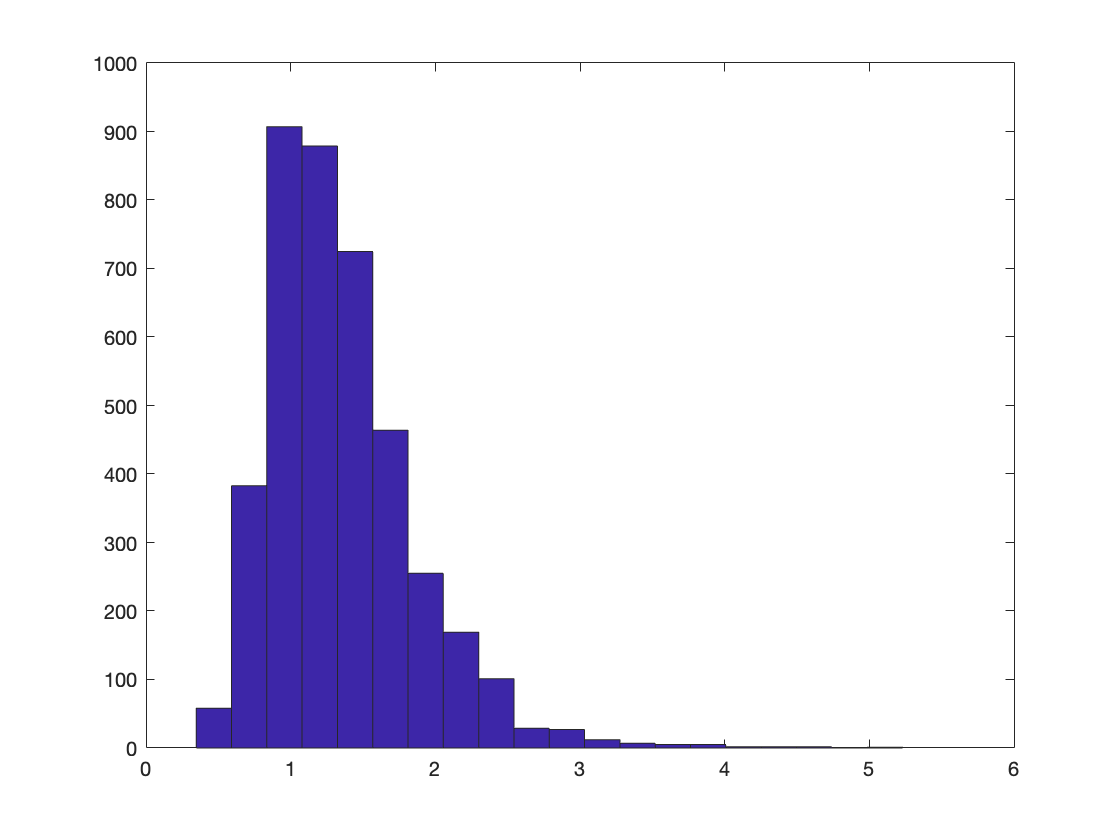

figure
hist(fano_pre,20)

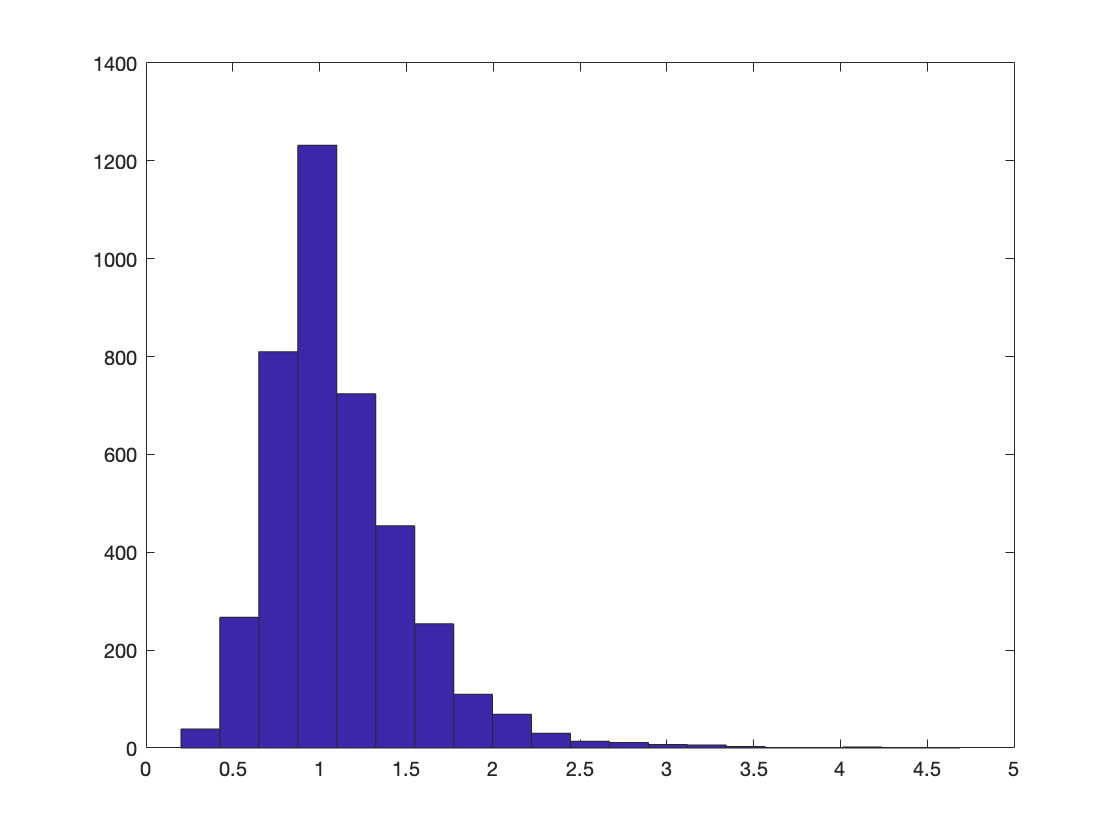

figure
hist(fano_post,20)


%yes, paired test. same neuron, just different time points.
%used wilcoxon signed-rank test.
%p = 6.15e-147

[p,h]=signrank(fano_pre,fano_post)

p = 6.1510e-147

h = logical
   1


function [FF] = calcfanofac(M,tstart,tend)
S = sum(M(:,tstart:tend),2);
FF = var(S,0,'all')./mean(S,'all');
end